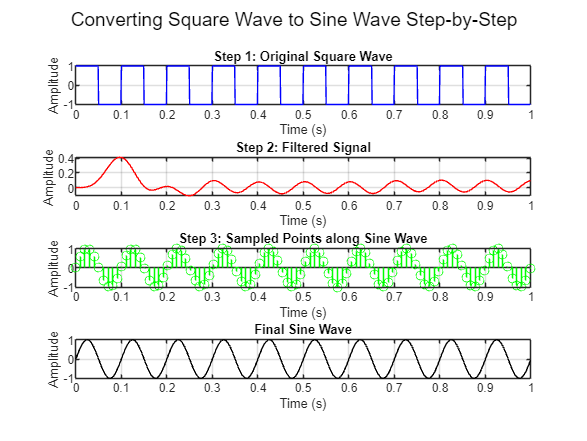

% Parameters
Fs = 1000;          % Sampling frequency (Hz)
f = 10;             % Frequency of the sine wave (Hz)
duration = 1;       % Duration of the signal (seconds)
t = 0:1/Fs:duration-1/Fs;   % Time vector

% Step 1: Generate the Square Wave
digital_signal = square(2*pi*f*t);

% Plot the original square wave
subplot(4, 1, 1);
plot(t, digital_signal, 'b');
title('Step 1: Original Square Wave');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Step 2: Low-pass Filtering
lpf_cutoff_freq = f/2;  % Nyquist frequency
[b, a] = butter(4, lpf_cutoff_freq / (Fs/2)); % 4th-order Butterworth LPF
filtered_signal = filter(b, a, digital_signal);

% Plot the filtered signal
subplot(4, 1, 2);
plot(t, filtered_signal, 'r');
title('Step 2: Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Step 3: Sampling along the Sine Wave
num_samples = 100; % Number of discrete data points
sample_indices = round(linspace(1, length(t), num_samples));
sine_wave_samples = sin(2*pi*f*t(sample_indices));

% Plot the sampled points along the sine wave
subplot(4, 1, 3);
stem(t(sample_indices), sine_wave_samples, 'g', 'Marker', 'o');
title('Step 3: Sampled Points along Sine Wave');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Step 4: Convert to Sine Wave
sine_wave = sin(2*pi*f*t);

% Plot the resulting sine wave
subplot(4, 1, 4);
plot(t, sine_wave, 'k');
title('Final Sine Wave');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Enable zooming
zoom on;

% Adjust subplot layout
sgtitle('Converting Square Wave to Sine Wave Step-by-Step');